% suppose we have a map that looks like this:
% note that there is no clear spatial pattern
n=30;
map2 = magic(n) 

map2 =    797   814   831   848   865   882   899     1    18    35    52    69    86   103   120   572   589   606   623   640   657   674   451   468   260   277   294   311   328   345
   813   830   847   864   881   898   690    17    34    51    68    85   102   119   121   588   605   622   639   656   673   465   467   484   276   293   310   327   344   346
   829   846   863   880   897   689   691    33    50    67    84   101   118   135   137   604   621   638   655   672   464   466   483   500   292   309   326   343   360   362
   845   862   879   896   688   705   707    49    66    83   100   117   134   136   153   620   637   654   671   463   480   482   499   516   308   325   342   359   361   378
   861   878   895   687   704   706   723    65    82    99   116   133   150   152   169   636   653   670   462   479   481   498   515   532   324   341   358   375   377   394
   877   894   686   703   720   722   739    81    98   115   132   149   151   168   1

% and suppose we have another map that we want to use to generate noise
% this map is not distirbuted according to a guassian, but it 
% has a clear spatial pattern that we want to preserve
map1 = ((1:n)' + (1:n)).^2 + n*n*(1:n)/2

map1 =          454         909        1366        1825        2286        2749        3214        3681        4150        4621        5094        5569        6046        6525        7006        7489        7974        8461        8950        9441        9934       10429       10926       11425       11926       12429       12934       13441       13950       14461
         459         916        1375        1836        2299        2764        3231        3700        4171        4644        5119        5596        6075        6556        7039        7524        8011        8500        8991        9484        9979       10476       10975       11476       11979       12484       12991       13500       14011       14524
         466         925        1386        1849        2314        2781        3250        3721        4194        4669        5146        5625        6106        6589        7074        7561        8050        8541        9034        9529       10026       10525       

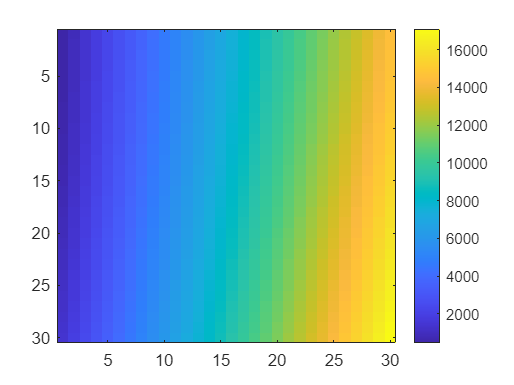

imagesc(map1); colorbar; % spatial pattern

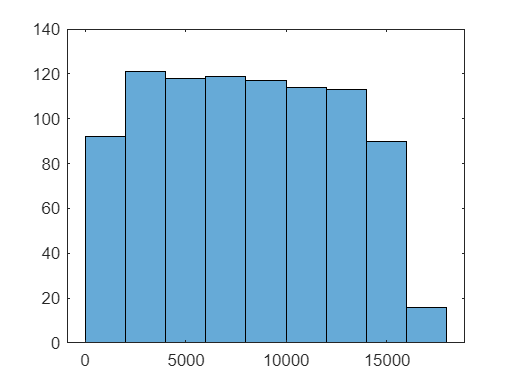

histogram(map1) % distribution

%% this is how we replace the data in map1 with noise distributed following
% a gaussian, whilst maintaining the same spatial pattern
sortNoise = sort(normrnd(0, 1, numel(map1), 1)); % make noise
% sortNoise = sort(noise(:)); % sort it
[~, idx] = sort(map1(:)); % get the spatial pattern of the template map
clear noise2;
noise2(idx) = sortNoise; % order the noise according to the spatial pattern
noise2 = reshape(noise2, size(map1)) %make is the correct shape

noise2 =    -4.3029   -2.0817   -1.5784   -1.4046   -1.2243   -1.0926   -0.9131   -0.8040   -0.7132   -0.6349   -0.5356   -0.4192   -0.3440   -0.2858   -0.1762   -0.0936   -0.0103    0.0794    0.1660    0.2632    0.3784    0.4362    0.5371    0.6418    0.7491    0.8187    0.9011    1.0300    1.1858    1.4025
   -3.3668   -2.0282   -1.5700   -1.3808   -1.2198   -1.0841   -0.9057   -0.8038   -0.7127   -0.6292   -0.5332   -0.4097   -0.3434   -0.2659   -0.1644   -0.0913    0.0003    0.0858    0.1684    0.2725    0.3839    0.4427    0.5450    0.6469    0.7618    0.8367    0.9056    1.0420    1.2250    1.4089
   -2.8915   -1.9698   -1.5615   -1.3667   -1.2014   -1.0812   -0.9037   -0.8036   -0.7008   -0.6278   -0.5247   -0.4051   -0.3334   -0.2620   -0.1639   -0.0821    0.0127    0.0907    0.1935    0.2760    0.3893    0.4504    0.5568    0.6843    0.7653    0.8406    0.9190    1.0648    1.2303    1.4388
   -2.6451   -1.9416   -1.5561   -1.3557   -1.1961   -1.0786   -0.9025   -0.7915   -0.70

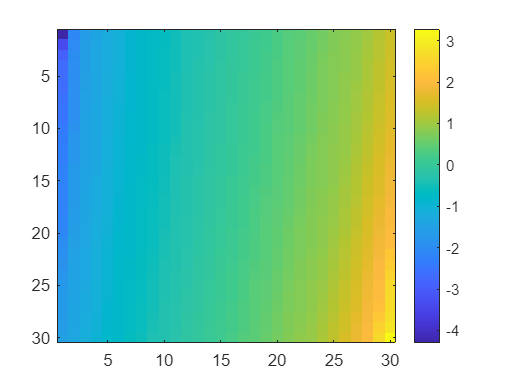

imagesc(noise2); colorbar

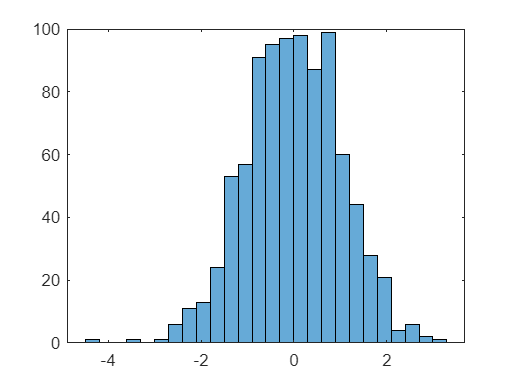

histogram(noise2)

% you can see that noise2 is normally distributed and has the same spatial
% pattern as the template map, map1

noise3 = resampleMatrix(map1, "gaussian", 'randParams', [100 20])

noise3 =    48.5335   58.8549   66.2317   71.5240   75.2275   77.7817   81.3265   83.5590   85.4819   86.9399   89.0385   91.0685   92.6534   94.7975   96.4801   98.2511   99.5686  101.3272  102.5584  104.9342  106.3207  107.9657  109.6693  111.5210  113.3071  115.4708  118.4257  121.1281  123.6672  127.8271
   49.9842   59.2812   66.2477   71.5663   75.2438   78.8116   81.3573   83.6104   85.4894   87.1129   89.0588   91.2633   92.6602   95.0079   96.6414   98.3694   99.8752  101.4603  102.6923  105.0439  106.4104  108.3123  109.9027  111.7938  113.5377  115.5516  118.4891  121.5608  124.0884  128.0558
   51.1672   59.7948   66.3912   71.5907   75.3228   78.9318   81.4397   83.6581   85.6508   87.1344   89.2986   91.2693   92.9833   95.0958   96.6570   98.6138   99.9103  101.5056  102.8202  105.2403  106.5459  108.4224  110.1039  112.0415  113.8801  115.5857  118.7617  122.0528  125.1967  128.4221
   51.3409   59.9897   66.4689   72.0820   75.4117   78.9903   81.6430   83.8500   85.74

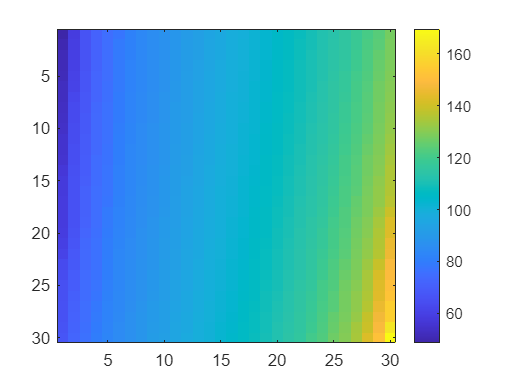

imagesc(noise3); colorbar

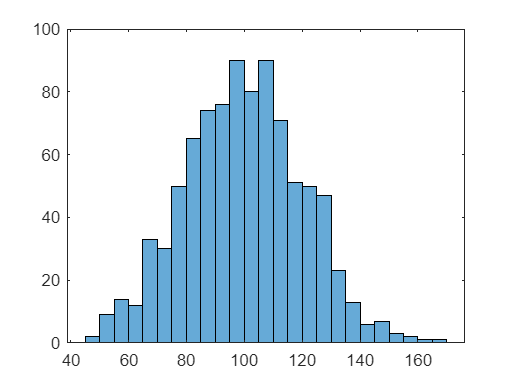

histogram(noise3)